data.Gain=double(imread('meshtest\Gain.tif'));
data.Offset=double(imread('meshtest\Offset.tif'));
data.Mesh=double(imread('meshtest\Mesh.tif'));
data.Obj=double(imread('meshtest\Obj.tif'));

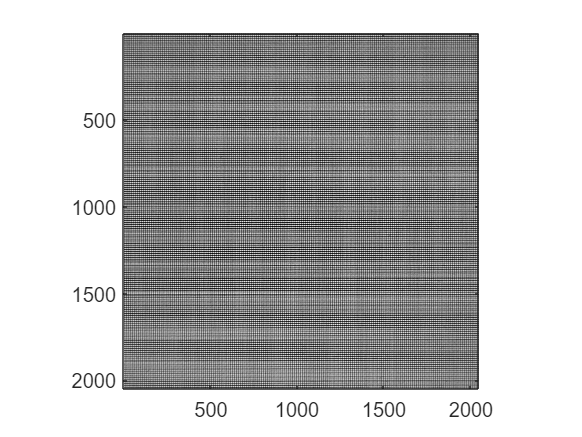

corrected.obj=(data.Obj-data.Offset)./(data.Gain-data.Offset);
corrected.mesh=(data.Mesh-data.Offset)./(data.Gain-data.Offset);
figure; imagesc(corrected.mesh); colormap gray; axis image

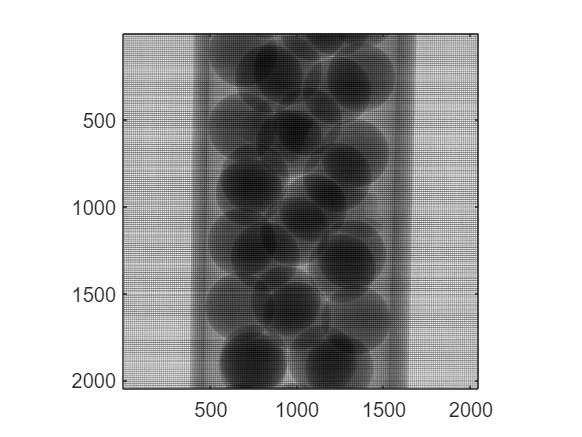

figure; imagesc(corrected.obj);  colormap gray; axis image

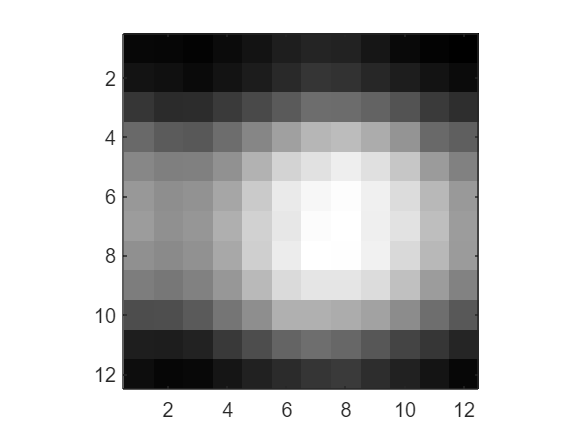

[crop.obj,rect] = imcrop(corrected.mesh,[1024,1024,11,11]);
[crop.mesh]     = imcrop(corrected.mesh,[1019,1019,16,16]);
figure; imagesc(crop.obj);  colormap gray; axis image

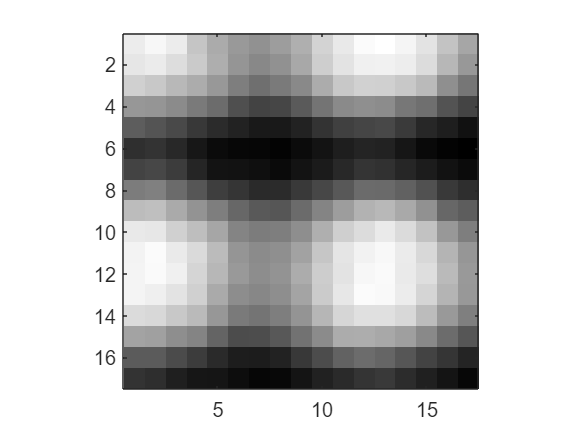

figure; imagesc(crop.mesh); colormap gray; axis image

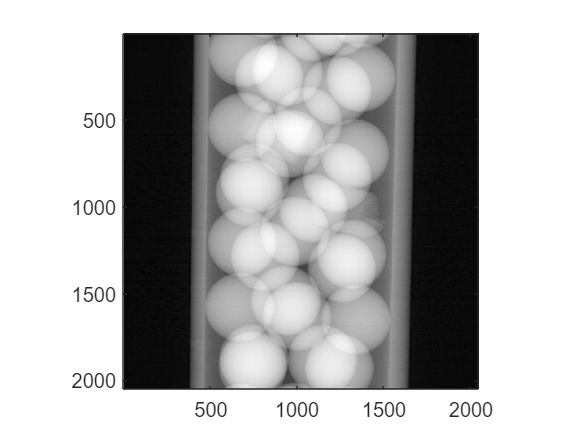

corrected.fulldivide=medfilt2(1-corrected.obj./imtranslate(corrected.mesh,[1,0]),[11,11]);
figure; imagesc(corrected.fulldivide); colormap gray; axis image

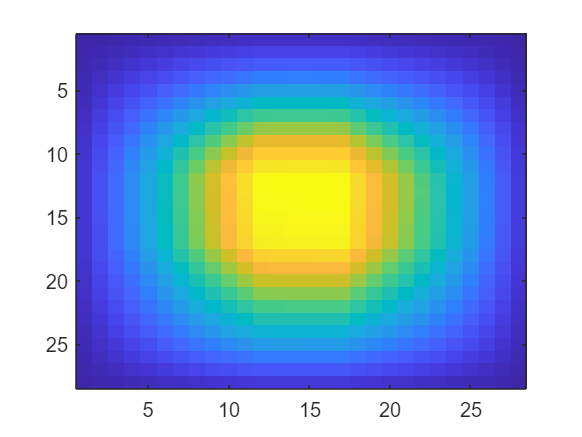

corr_om=xcorr2(crop.obj,crop.mesh);
[maxc,maxic]=max(corr_om(:));
[ij,ji] = ind2sub(size(corr_om),maxic);
figure; imagesc(corr_om);

corrected.fftmesh=fft2(corrected.mesh);
corrected.fftobj=fft2(corrected.obj);


blankslate1=zeros(size(corrected.obj));
blankslate2=zeros(size(corrected.obj));
tic
for i = 800:1600
    for j = 800:1600
        [crop.obj1,rect1] = imcrop(corrected.obj,[i,j,9,9]);
        [crop.mesh1]     = imcrop(corrected.mesh,rect1);
        [crop.obj2,rect2] = imcrop(corrected.obj,[i,j,9,9]);
        [crop.mesh2]     = imcrop(corrected.mesh,rect2);
        avg=mean2(crop.obj1)/mean2(crop.mesh1);
        ratio=real(ifft2(fft2(crop.obj2)./fft2(crop.mesh2)));
        ratio=mean2(ratio);
        blankslate1(j,i)=avg;
        blankslate2(j,i)=ratio;
    end
end
toc

Elapsed time is 25.156761 seconds.


sharpabs=1-imcrop(blankslate1,[1000,1000,300,300]);
blurabs=1-imcrop(blankslate2,[1000,1000,300,300]);
corrected.cropfulldivide=imcrop(corrected.fulldivide,[1000,1000,300,300]);

Unrecognized field name "fulldivide".

figure; imagesc(1-imcrop(blankslate1,[1000,1000,300,300])); colormap gray; axis image
figure; imagesc(1-imcrop(blankslate2,[1000,1000,300,300])); colormap gray; axis image
figure; imagesc(imcrop(corrected.fulldivide,[1000,1000,300,300])); colormap gray; axis image


ABS='D:/.research/Research/mesh_based/231025/Processed/ABS/'

ABS = 'D:/.research/Research/mesh_based/231025/Processed/ABS/'

ABSdir = dir(fullfile(ABS,'*.mat'));
for k = 1:numel(ABSdir)
    F = dir(fullfile(ABS,ABSdir(k).name));
    ABSdir(k).data = load(strcat(F.folder,'/',F.name));
end